# 1.2.3. Сбор данных

**Лекция**

## Импорт файлов: краткий обзор

В MATLAB есть возможность импортировать и экспортировать данные в разные форматы. Как правило, экспорт или импорт осуществляется:

    **●  **Из **таблиц** Microsoft Exel

    **●  **Из **текстовых** **файлов**

    **●  **Импорт **изображений** (JPEG, TIFF, PNG и другие форматы)

    **●  **Импорт **научных данных** (NetCDF, HDF, FITS и CDF форматы)

    **●  **Импорт **аудио** и **видео** (для их последующей обработки) будет подробно рассмотрена в лекции 1.2.17 "Цифровая обработка сигналов"

Помимо этого имеется возможность считывать и записывать данные через TCP/IP протокол, считывать данные напрямую из интернета, и др.

## Сохранение данных, MAT-файлы

Данные из Workspace можно сохранять в mat-файлы с помощью команды `save`:

M1 = 3*randn(4); T1 = "Доброе утро";  % переменные, которые хотелось бы сохранить в файл
save('data03_import_lect1.mat','M1','T1')        % сохраняем
%clear  % Очищаем workspace

Данные из MAT-файла можно импортировать с помощью команды `load`:

load('data03_import_lect2.mat') % в этом MAT-файле хранятся переменные M2 и T2

Альтернативным способом сохранить данные из Workspace можно через GUI:

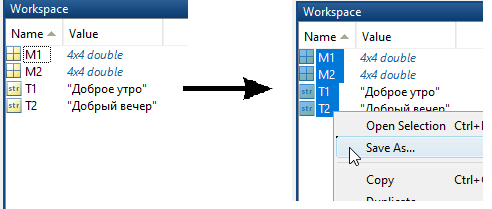

## Импорт данных из таблиц Exel

Импорт осуществляется с помощью функции `readtable`:

T = readtable('airlinesmall_table_big.xlsx', 'Sheet','2008');   % выбор листа с именем '2008'
T(1:10,1:20)

ans = 10×20 table
    Year    Month    DayofMonth    DayOfWeek    DepTime    CRSDepTime    ArrTime    CRSArrTime    UniqueCarrier    FlightNum    TailNum     ActualElapsedTime    CRSElapsedTime    AirTime    ArrDelay    DepDelay    Origin    Dest     Distance    TaxiIn
    ____    _____    __________    _________    _______    __________    _______    __________    _____________    _________    ________    _________________    ______________

Пример считатывания выбранных столбцов:

T3 = readtable('airlinesmall_table_big.xlsx', 'Sheet','1996','Range','A1:E9')

T3 = 8×5 table
    Year    Month    DayofMonth    DayOfWeek    DepTime
    ____    _____    __________    _________    _______

    1996      1          18            4         2117  
    1996      1          12            5         1252  
    1996      1          16            2         1441  
    1996      1           1            1         2258  
    1996      1           4            4         1814  
    1996      1          31            3         1822  
    1996      1          18            4          729  
    1996      1          26            5         1704  


Можно также осуществлять экспорт таблиц в формат Exel:

writetable(T3,'data03_import_lect1.xlsx');

Рекомендация преподавателям: покажите студентам возможность импорта таблиц Excel через GUI.

## Импорт данных из текстовых файлов

Для импорта текста используется команда `fileread`:

Phrase = fileread('data03_import_lect1.txt')

Phrase = 'Здесь только  импортированный текст: никаких данных здесь нет. '

Имеется также возможность импортировать таблицу. Если в текстовом файле данные разграничиваются каким-либо символом (`','` или `\t` (TAB-пробел)), то это учитвывается параметром `'Delimiter'`:

%writetable(T(:,1:19),'data03_import_lect2.txt', 'Delimiter','|')
T4 = readtable('data03_import_lect2.txt', 'Delimiter','|')

T4 = 1753×19 table
    Year    Month    DayofMonth    DayOfWeek    DepTime    CRSDepTime    ArrTime    CRSArrTime    UniqueCarrier    FlightNum    TailNum     ActualElapsedTime    CRSElapsedTime    AirTime    ArrDelay    DepDelay    Origin    Dest     Distance
    ____    _____    __________    _________    _______    __________    _______    __________    _____________    _________    ________    _________________    ______________    _______<

## Чтение изображений

Изображения импортируются в трехмерный массив (попиксельно) с помощью команды `imread`:

Picture = imread('BFS_rocket.jpg')

Picture = 600×1000×3 uint8 array
Picture(:,:,1) =

    34    34    34    34    34    34    34    34    36    36    36    36    36    36    36    36    34    34    35    35    35    35    35    36    36    36    36    36    36    37    37    37    39    39    39    39    39    40    40    40    40    41    42    43    43    43    43    43    46    46    47    48    49    49    49    48    52    52    53    53    54    55    55    56    58    55    57    64    66    62    60    63    63    65    66    67    68    70    73    76    74    72    71    73    75    76    76    74    76    75    75    76    78    79    78    75    72    71    71    71    70    70    69    69    69    69    69    68    67    66    65    65    65    66    66    65    64    64    63    63    61    61    61    61    61    61    61    61    61    61    61    61    61    61    61    61    61    61    62    62    61    61    60    59    59    58    58    58    57    57    56    56    60    59    58    57    57    59 

Для отображения изображения используется команда `imshow`:

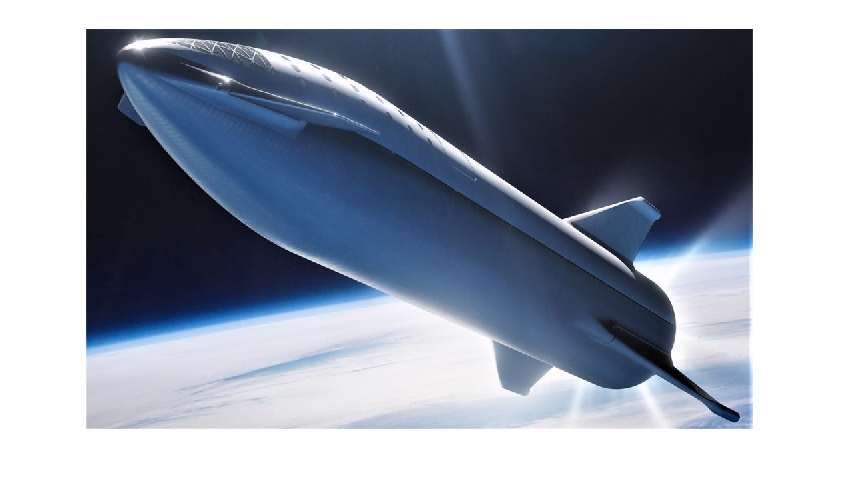

imshow(Picture)

Можно также вручную обращаться к пикселям:

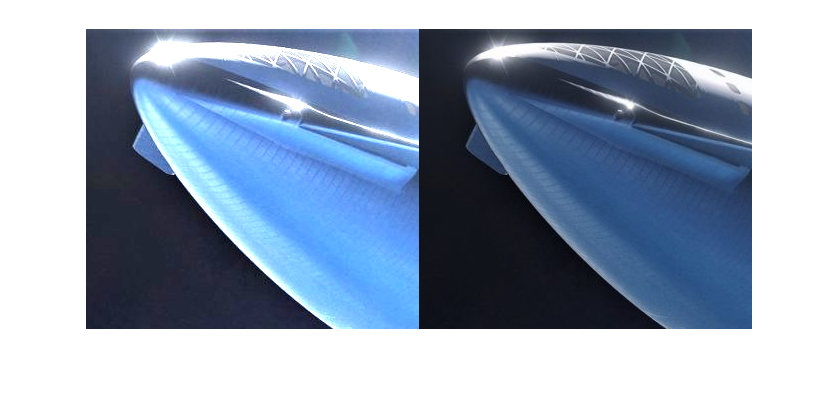

Picture1 = Picture(1:round(end/2), 1:round(end/3),:);
Picture1 = [Picture1*2,Picture1];
imshow(Picture1)